# STEP 5 — SO(3) GEOMETRIC CONTROLLER

This file takes the desired trajectory from Step 2 and the estimated state from Step 4 and converts their differences into commands for the drone. The position and velocity errors first produce a desired translational acceleration. That acceleration determines the force the vehicle must generate, and the force direction is used to construct a desired attitude on SO(3). The attitude error and angular-velocity error are then converted into a torque command.

## 1. Prepare the controller inputs

The controller starts by clearing the workspace and loading the common MAT-file. The quantities needed here are the desired position, velocity and acceleration from Step 2 and the estimated position, velocity, attitude and angular velocity from Step 4.


$$\mathbf p_d,\;\mathbf v_d,\;\mathbf a_d,\qquad \hat{\mathbf p},\;\hat{\mathbf v},\;\hat R,\;\hat{\mathbf\omega}$$


The controller must use the estimated state rather than the true state. Otherwise the controller would have perfect knowledge and the sensing/estimation stages would have no effect on the closed loop.

clc;
clear;
close all;

The measurement file is loaded here so the controller can access the outputs of the earlier stages. In particular, the desired trajectory and the estimated state become available to the control law.


$$\text{controller input}=\{\mathbf p_d,\mathbf v_d,\mathbf a_d,\hat{\mathbf p},\hat{\mathbf v},\hat R,\hat{\mathbf{\omega}}\}$$


load('drone_toy_model.mat');
whos

  Name                       Size                Bytes  Class     Attributes

  R_camera                   3x3x1001            72072  double              
  R_est_history              3x3x1001            72072  double              
  R_true                     3x3x1001            72072  double              
  T                          1x1                     8  double              
  a0                         1x3                    24  double              
  a_imu                   1001x3                 24024  double              
  a_true                  1001x3                 24024  double              
  accel_bias                 1x3                    24  double              
  ad                      1001x3                 24024  double              
  af                         1x3                    24  double              
  attitude_RMSE              1x1                     8  double              
  ba_est_history          1001x3                 24024  double             

This block explicitly documents the data interface of Step 5 and obtains numSamples. The quantities listed as inputs are the only state information the controller should need: reference quantities from Step 2 and estimated quantities from Step 4.

%% ========================================================
% STEP 5: SO(3) GEOMETRIC CONTROLLER
%
% INPUTS FROM STEP 2:
%   t
%   pd
%   vd
%   ad
%
% INPUTS FROM STEP 4:
%   p_est_history
%   v_est_history
%   R_est_history
%   omega_est_history
%
% OUTPUTS FOR STEP 6:
%   acceleration_command
%   force_command
%   desired_thrust
%   R_desired_history
%   attitude_error_history
%   torque_command
% ========================================================

%% --------------------------------------------------------
% 1. Load previous results
% ---------------------------------------------------------

load('drone_toy_model.mat');

numSamples = length(t);

## 2. Check inputs, define physical parameters and gains

The first practical block checks that the previous stages have been executed and that the required variables exist. It then defines gravity, mass, inertia and the body z-axis e3.


$$\mathrm g=[0\;0\;-9.81]^T,\qquad J=\mathrm{diag}(J_x,J_y,J_z)$$


The controller gains determine how strongly position, velocity, attitude and angular-velocity errors are corrected.


$$K_p=\mathrm{diag}(k_{px},k_{py},k_{pz}),\qquad K_v=\mathrm{diag}(k_{vx},k_{vy},k_{vz})$$



$$K_R=\mathrm{diag}(k_{Rx},k_{Ry},k_{Rz}),\qquad K_\omega=\mathrm{diag}(k_{\omega x},k_{\omega y},k_{\omega z})$$


The history arrays are allocated so every command and error can later be plotted and passed to the dynamics simulation.


%% --------------------------------------------------------
% 2. Check required variables
% ---------------------------------------------------------

requiredVariables = {
    't'
    'pd'
    'vd'
    'ad'
    'p_est_history'
    'v_est_history'
    'R_est_history'
    'omega_est_history'
};

for i = 1:length(requiredVariables)

    if ~exist(requiredVariables{i},'var')

        error(['Missing variable: ', ...
               requiredVariables{i}, ...
               '. Run the previous step first.']);

    end

end

%% --------------------------------------------------------
% 3. Gravity and drone parameters
% ---------------------------------------------------------

g = [0; 0; -9.81];

m = 1.0;                         % kg

J = diag([0.02 0.02 0.04]);      % kg*m^2

e3 = [0; 0; 1];

%% --------------------------------------------------------
% 4. Controller gains
% ---------------------------------------------------------

Kp = diag([4 4 6]);

Kv = diag([3 3 4]);

KR = diag([4 4 2]);

Komega = diag([0.15 0.15 0.10]);

%% --------------------------------------------------------
% 5. Storage
% ---------------------------------------------------------

acceleration_command = ...
    zeros(numSamples,3);

force_command = ...
    zeros(numSamples,3);

desired_thrust = ...
    zeros(numSamples,1);

R_desired_history = ...
    zeros(3,3,numSamples);

attitude_error_history = ...
    zeros(numSamples,3);

torque_command = ...
    zeros(numSamples,3);

## 3. Position and velocity feedback

At each time sample the controller reads the estimated state. The position error is defined as desired minus estimated position, and the velocity error is defined in the same way.


$$\mathbf e_p=\mathbf p_d-\hat{\mathbf p},\qquad\mathbf e_v=\mathbf v_d-\hat{\mathbf v}$$


These signs are deliberate: if the drone is behind the desired position, e_p points toward the desired position. The gains then turn these errors into corrective acceleration.

The desired trajectory already supplies a feed-forward acceleration a_d. Feedback terms K_p e_p and K_v e_v are added to correct tracking error.


$$\mathbf a_c=\mathbf a_d+K_p\mathbf e_p+K_v\mathbf e_v$$


Here a_c is the acceleration command, a_d is the planned acceleration, Kp is the proportional position gain, Kv is the velocity gain, e_p is position error and e_v is velocity error. This equation is the translational control law used by the toy model.

The drone dynamics obey m a = F + m g. Therefore, if the controller asks for inertial acceleration a_c, the required non-gravitational force is obtained by rearranging Newton’s second law.


$$m\mathbf a_c=\mathbf F_d+m\mathbf g$$



$$\mathbf F_d=m(\mathbf a_c-\mathbf g)$$


m is the drone mass, g is the gravity vector and F_desired is the force that must be generated by the rotors. The controller therefore changes a tracking problem into a force-generation problem.

A quadrotor produces thrust approximately along its body z-axis. Consequently, the direction in which the body z-axis should point is the direction of the desired force.


$$\mathbf b_{3d}=\frac{\mathbf F_d}{\|\mathbf F_d\|}$$


If the desired force is almost zero, the direction would be undefined, so the code uses the world z-axis e3 as a safe fallback. The variable b3d is the third column of the desired rotation matrix.

A force vector determines two degrees of freedom of attitude but does not uniquely determine rotation about that force direction. We therefore use the desired horizontal velocity direction to specify a heading.


$$\psi_d=\mathrm{atan2}(v_{dy},v_{dx})$$


The vector b1_heading = [cos(psi_d), sin(psi_d), 0]^T is a horizontal direction representing the desired heading. It is used only to remove the remaining yaw ambiguity.

We now have a desired third body axis b3d and a heading direction b1_heading. Their cross product gives a vector perpendicular to both.


$$\mathbf b_{2d}=\frac{\mathbf b_{3d}\times\mathbf b_{1h}}{\|\mathbf b_{3d}\times\mathbf b_{1h}\|}$$


The first body axis is then obtained from b2d and b3d.


$$\mathbf b_{1d}=\mathbf b_{2d}\times\mathbf b_{3d}$$


Putting the three orthonormal body axes into columns gives the desired attitude.


$$R_d=\left[\matrix{\mathbf b_{1d}&\mathbf b_{2d}&\mathbf b_{3d}} \right]$$


If b3d and the heading direction become nearly parallel, the cross product becomes too small. The fallback heading prevents this singular construction.

The numerically constructed Rd should be a rotation matrix, but finite precision can introduce small deviations from orthogonality. The same SVD projection used in the estimator is applied here.


$$R_d^TR_d=I,\qquad\det(R_d)=1$$


This ensures that the attitude sent to the attitude controller is a proper member of SO(3), not an arbitrary 3-by-3 matrix.

The attitude error is defined geometrically rather than by subtracting matrix elements. For the desired attitude Rd and estimated attitude Rhat, the skew-symmetric part of Rd^T Rhat represents the local rotational error.


$$\mathbf e_R=\frac12\left(R_d^T\hat R-\hat R^TR_d\right)^\vee$$


The vee operator extracts the three independent components of a skew-symmetric matrix. Thus e_R is a three-vector whose components represent the local rotation error about the x, y and z axes.

The toy model assumes zero desired angular velocity. Therefore the angular-velocity error is simply the estimated angular velocity relative to zero.


$$\mathbf e_\omega=\hat{\mathbf\omega}-\mathbf{\omega}_d,\qquad\mathbf{\omega}_d=\mathbf0$$


The geometric torque controller combines proportional attitude feedback, angular-rate damping and the rigid-body gyroscopic compensation term.


$$\mathbf{\tau}=-K_R\mathbf e_R-K_\omega\mathbf e_\omega+\hat{\mathbf\omega}\times(J\hat{\mathbf\omega})$$


tau is the commanded body torque and J is the inertia matrix. The cross product term accounts for the angular-momentum coupling already present in Euler’s rigid-body equation.

Once the desired force direction is used as the desired body z-axis, the required thrust magnitude is the magnitude of the desired force.


$$T=\mathbf F_d^T\mathbf b_{3d}=\|\mathbf F_d\|$$


T is measured in newtons. It is stored separately because Step 6 uses it as the scalar thrust command applied to the rigid-body model.


%% --------------------------------------------------------
% 6. SO(3) geometric controller
% ---------------------------------------------------------

for k = 1:numSamples

    %% ====================================================
    % A. Estimated state from STEP 4
    % ====================================================

    p_hat = ...
        p_est_history(k,:)';

    v_hat = ...
        v_est_history(k,:)';

    R_hat = ...
        R_est_history(:,:,k);

    omega_hat = ...
        omega_est_history(k,:)';

    %% ====================================================
    % B. Position error
    %
    % e_p = p_d - p_hat
    % ====================================================

    e_p = ...
        pd(k,:)' - p_hat;

    %% ====================================================
    % C. Velocity error
    %
    % e_v = v_d - v_hat
    % ====================================================

    e_v = ...
        vd(k,:)' - v_hat;

    %% ====================================================
    % D. Desired acceleration
    %
    % a_c =
    % a_d + K_p e_p + K_v e_v
    % ====================================================

    a_cmd = ...
        ad(k,:)' ...
        + Kp*e_p ...
        + Kv*e_v;

    acceleration_command(k,:) = ...
        a_cmd';

    %% ====================================================
    % E. Desired force
    %
    % F_d = m(a_c - g)
    % ====================================================

    F_desired = ...
        m * (a_cmd - g);

    force_command(k,:) = ...
        F_desired';

    %% ====================================================
    % F. Desired thrust direction
    %
    % b_3d = F_d / ||F_d||
    % ====================================================

    if norm(F_desired) < 1e-8

        b3d = e3;

    else

        b3d = ...
            F_desired / norm(F_desired);

    end

    %% ====================================================
    % G. Desired yaw
    %
    % Yaw follows horizontal velocity direction.
    % ====================================================

    if norm(vd(k,1:2)) > 1e-4

        yaw_d = ...
            atan2( ...
                vd(k,2), ...
                vd(k,1));

    else

        yaw_d = 0;

    end

    b1_heading = [
        cos(yaw_d);
        sin(yaw_d);
        0
    ];

    %% ====================================================
    % H. Construct desired attitude R_d
    % ====================================================

    b2d_temp = ...
        cross(b3d,b1_heading);

    %% Handle singular configuration

    if norm(b2d_temp) < 1e-8

        b1_heading = [1; 0; 0];

        b2d_temp = ...
            cross(b3d,b1_heading);

    end

    %% Normalize second body axis

    b2d = ...
        b2d_temp / norm(b2d_temp);

    %% Construct first body axis

    b1d = ...
        cross(b2d,b3d);

    %% Desired rotation matrix

    Rd = [
        b1d  b2d  b3d
    ];

    %% ====================================================
    % I. Ensure R_d belongs to SO(3)
    %
    % R_d^T R_d = I
    % det(R_d) = 1
    % ====================================================

    [U,~,V] = svd(Rd);

    Rd = U*V';

    if det(Rd) < 0

        U(:,3) = -U(:,3);

        Rd = U*V';

    end

    R_desired_history(:,:,k) = ...
        Rd;

    %% ====================================================
    % J. SO(3) attitude error
    %
    % e_R =
    % 1/2 (R_d^T R - R^T R_d)^vee
    % ====================================================

    E_R = ...
        0.5 * ...
        ( ...
        Rd'*R_hat ...
        - ...
        R_hat'*Rd ...
        );

    e_R = ...
        vee(E_R);

    attitude_error_history(k,:) = ...
        e_R';

    %% ====================================================
    % K. Desired angular velocity
    %
    % For this toy controller:
    %
    % omega_d = 0
    %
    % This is the same simplified formulation used in
    % our current mathematical model.
    % ====================================================

    omega_d = ...
        zeros(3,1);

    %% ====================================================
    % L. Angular velocity error
    %
    % e_omega = omega_hat - omega_d
    % ====================================================

    e_omega = ...
        omega_hat - omega_d;

    %% ====================================================
    % M. Geometric torque controller
    %
    % tau =
    % -K_R e_R
    % -K_omega e_omega
    % + omega x J omega
    % ====================================================

    tau = ...
        -KR*e_R ...
        -Komega*e_omega ...
        +cross( ...
            omega_hat, ...
            J*omega_hat);

    torque_command(k,:) = ...
        tau';

    %% ====================================================
    % N. Required thrust magnitude
    %
    % T = ||F_d||
    % ====================================================

    T = ...
        norm(F_desired);

    desired_thrust(k) = ...
        T;

end

## 13. Inspect the controller errors and commands

The next block converts the three-component attitude error into a scalar magnitude and computes the position-error magnitude. These are useful compact measures for plots and RMS calculations.


$$\|\mathbf e_R\|=\sqrt{e_{Rx}^2+e_{Ry}^2+e_{Rz}^2},\qquad\|\mathbf e_p\|=\sqrt{e_x^2+e_y^2+e_z^2}$$


The controller then plots acceleration, thrust, torque and tracking errors. These plots show exactly what the controller is asking the physical model to do, before Step 6 determines what the drone actually does in response.


%% ========================================================
% 7. Attitude error magnitude
% =========================================================

attitude_error_magnitude = ...
    sqrt( ...
        sum( ...
            attitude_error_history.^2, ...
            2));

%% ========================================================
% 8. SO(3) validity checks
% =========================================================

rotation_orthogonality_error = ...
    zeros(numSamples,1);

rotation_determinant_error = ...
    zeros(numSamples,1);

for k = 1:numSamples

    R = ...
        R_desired_history(:,:,k);

    rotation_orthogonality_error(k) = ...
        norm( ...
            R'*R - eye(3), ...
            'fro');

    rotation_determinant_error(k) = ...
        abs(det(R)-1);

end

%% ========================================================
% 9. Position error used by controller
% =========================================================

position_error_history = ...
    pd - p_est_history;

position_error_magnitude = ...
    sqrt( ...
        sum( ...
            position_error_history.^2, ...
            2));

velocity_error_history = ...
    vd - v_est_history;

%% ========================================================
% 10. Plot controller acceleration
% =========================================================

figure;

plot( ...
    t, ...
    acceleration_command(:,1), ...
    'LineWidth',1.3);

hold on;

plot( ...
    t, ...
    acceleration_command(:,2), ...
    'LineWidth',1.3);

plot( ...
    t, ...
    acceleration_command(:,3), ...
    'LineWidth',1.3);

xlabel('Time (s)');
ylabel('Acceleration (m/s^2)');

title('SO(3) Controller Acceleration Command');

legend( ...
    'a_x', ...
    'a_y', ...
    'a_z');

grid on;

The thrust plot shows the scalar force magnitude requested from the rotors over time. It is compared with the physical reference of hover thrust in the interpretation of the results.


$$T=\|\mathbf F_d\|$$


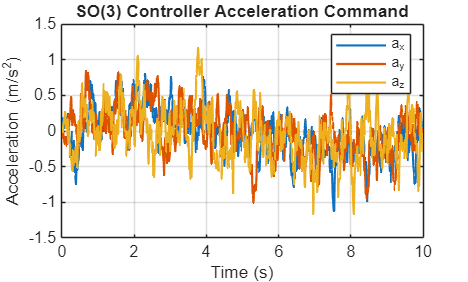

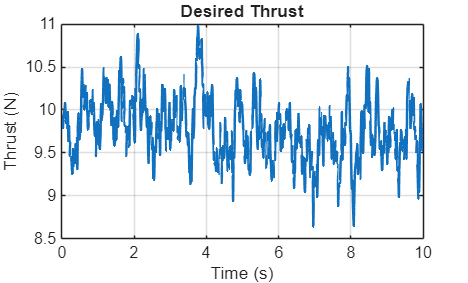


%% ========================================================
% 11. Plot desired thrust
% =========================================================

figure;

plot( ...
    t, ...
    desired_thrust, ...
    'LineWidth',1.5);

xlabel('Time (s)');
ylabel('Thrust (N)');

title('Desired Thrust');

grid on;

%% ========================================================
% 12. Plot SO(3) attitude error
% =========================================================

figure;

plot( ...
    t, ...
    attitude_error_history(:,1), ...
    'LineWidth',1.2);

hold on;

plot( ...
    t, ...
    attitude_error_history(:,2), ...
    'LineWidth',1.2);

plot( ...
    t, ...
    attitude_error_history(:,3), ...
    'LineWidth',1.2);

xlabel('Time (s)');
ylabel('SO(3) Attitude Error');

title('SO(3) Attitude Error');

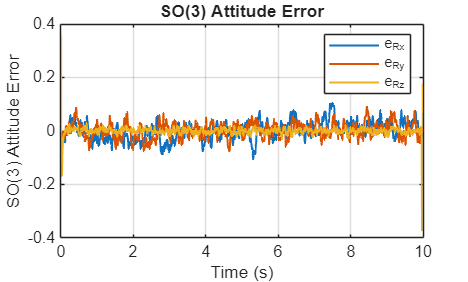


legend( ...
    'e_{Rx}', ...
    'e_{Ry}', ...
    'e_{Rz}');

grid on;

%% ========================================================
% 13. Plot torque
% =========================================================

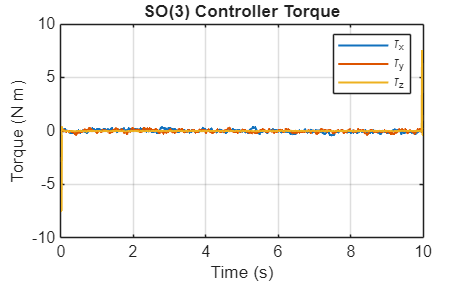


figure;

plot( ...
    t, ...
    torque_command(:,1), ...
    'LineWidth',1.2);

hold on;

plot( ...
    t, ...
    torque_command(:,2), ...
    'LineWidth',1.2);

plot( ...
    t, ...
    torque_command(:,3), ...
    'LineWidth',1.2);

xlabel('Time (s)');
ylabel('Torque (N m)');

title('SO(3) Controller Torque');

legend( ...
    '\tau_x', ...
    '\tau_y', ...
    '\tau_z');

grid on;

The next plot shows the position error presented to the controller, while the printed values calculate RMS errors and peak actuator demands. These numbers describe the command being produced, before the rigid-body dynamics determine the actual response.


$$RMSE_x=\sqrt{\frac1N\sum e_{p,x}^2},\qquad T_{max}=\max_k T_k$$


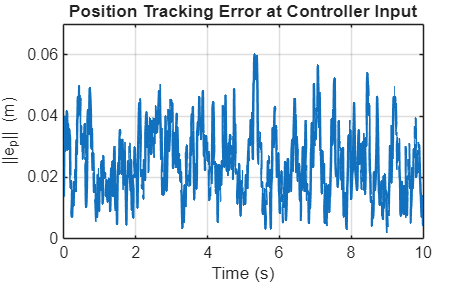


%% ========================================================
% 14. Position error seen by controller
% =========================================================

figure;

plot( ...
    t, ...
    position_error_magnitude, ...
    'LineWidth',1.5);

xlabel('Time (s)');
ylabel('||e_p|| (m)');

title('Position Tracking Error at Controller Input');

grid on;


%% ========================================================
% 15. Display results
% =========================================================

fprintf('\n');
fprintf('============================================\n');
fprintf('STEP 5 - SO(3) CONTROLLER RESULTS\n');

STEP 5 - SO(3) CONTROLLER RESULTS


fprintf('============================================\n');


fprintf('\nPosition error RMS:\n');

fprintf('X = %.4f m\n', ...


Position error RMS:


    sqrt(mean(position_error_history(:,1).^2)));

X = 0.0149 m



fprintf('Y = %.4f m\n', ...
    sqrt(mean(position_error_history(:,2).^2)));

Y = 0.0170 m



fprintf('Z = %.4f m\n', ...
    sqrt(mean(position_error_history(:,3).^2)));

fprintf('\nVelocity error RMS:\n');


Z = 0.0154 m



Velocity error RMS:


fprintf('X = %.4f m/s\n', ...
    sqrt(mean(velocity_error_history(:,1).^2)));

X = 0.0639 m/s



fprintf('Y = %.4f m/s\n', ...
    sqrt(mean(velocity_error_history(:,2).^2)));

Y = 0.0712 m/s



fprintf('Z = %.4f m/s\n', ...
    sqrt(mean(velocity_error_history(:,3).^2)));

Z = 0.0632 m/s



fprintf('\nMaximum thrust = %.4f N\n', ...
    max(desired_thrust));

fprintf('Mean thrust = %.4f N\n', ...
    mean(desired_thrust));


Maximum thrust = 10.9771 N


Mean thrust = 9.7764 N



fprintf('\nMaximum torque:\n');


Maximum torque:



fprintf('tau_x = %.4f N m\n', ...
    max(abs(torque_command(:,1))));

tau_x = 0.4194 N m



fprintf('tau_y = %.4f N m\n', ...
    max(abs(torque_command(:,2))));

tau_y = 0.3707 N m



fprintf('tau_z = %.4f N m\n', ...
    max(abs(torque_command(:,3))));

tau_z = 7.4887 N m



fprintf('\nSO(3) attitude error RMS = %.4f\n', ...
    sqrt(mean(attitude_error_magnitude.^2)));


SO(3) attitude error RMS = 0.0491



fprintf('\nMaximum rotation orthogonality error = %.4e\n', ...
    max(rotation_orthogonality_error));



Maximum rotation orthogonality error = 1.3515e-15


fprintf('Maximum determinant error = %.4e\n', ...
    max(rotation_determinant_error));

Maximum determinant error = 8.8818e-16


## 14. Save the controller outputs

The final block saves the desired attitude, thrust, torque, acceleration and tracking-error histories. These are the inputs required by the dynamics simulation.


$$\mathcal U_k=\{\mathbf F_{d,k},T_k,R_{d,k},\mathbf{\tau}_k\}$$


The controller therefore produces a complete command sequence but does not itself move the drone. Physical motion is simulated in Step 6.

This command opens the saved MAT-file for direct inspection. It is a workspace/data check rather than another control calculation.

open("drone_toy_model.mat")

ans = struct with fields:
              R_camera: [3×3×1001 double]
         R_est_history: [3×3×1001 double]
                R_true: [3×3×1001 double]
                     T: 10
                    a0: [0 0 0]
                 a_imu: [1001×3 double]
                a_true: [1001×3 double]
            accel_bias: [0.0200 -0.0100 0.0300]
                    ad: [1001×3 double]
                    af: [0 0 0]
         attitude_RMSE: 0.0252
        ba_est_history: [1001×3 double]
        bg_est_history: [1001×3 double]
                    dt: 0.0100
             gyro_bias: [0.0050 -0.0030 0.0020]
     omega_est_history: [1001×3 double]
             omega_imu: [1001×3 double]
            omega_true: [1001×3 double]
                    p0: [0 0 0]
              p_camera: [1001×3 double]
         p_est_history: [1001×3 double]
                p_true: [1001×3 double]
                    pd: [1001×3 double]
                    pf: [5 4 3]
         position_RMSE: [0.0149 0.0170 0.0154]
    sigm

%% ========================================================
% 16. Save Step 5 results
% =========================================================

save( ...
    'drone_toy_model.mat', ...
    'p0', ...
    'pf', ...
    'v0', ...
    'vf', ...
    'a0', ...
    'af', ...
    'T', ...
    't', ...
    'dt', ...
    'pd', ...
    'vd', ...
    'ad', ...
    'p_true', ...
    'v_true', ...
    'a_true', ...
    'R_true', ...
    'omega_true', ...
    'p_camera', ...
    'R_camera', ...
    'a_imu', ...
    'omega_imu', ...
    'p_est_history', ...
    'v_est_history', ...
    'R_est_history', ...
    'omega_est_history', ...
    'ba_est_history', ...
    'bg_est_history', ...
    'acceleration_command', ...
    'force_command', ...
    'desired_thrust', ...
    'R_desired_history', ...
    'attitude_error_history', ...
    'torque_command', ...
    'position_error_history', ...
    'velocity_error_history', ...
    'position_error_magnitude', ...
     'position_RMSE', ...
     'velocity_RMSE', ...
     'attitude_RMSE', ...
     'sigma_position', ...
    'sigma_camera_angle', ...
    'sigma_acceleration', ...
    'sigma_gyro', ...
    'accel_bias', ...
    'gyro_bias');

fprintf('\nStep 5 results saved to drone_toy_model.mat\n');


Step 5 results saved to drone_toy_model.mat



%% ========================================================
% LOCAL FUNCTIONS
% =========================================================

function S = skew(v)

    S = [
         0    -v(3)  v(2);
         v(3)  0    -v(1);
        -v(2) v(1)   0
    ];

end


function v = vee(S)

    v = [
        S(3,2);
        S(1,3);
        S(2,1)
    ];

end

The final reload confirms that the controller outputs were written to the shared MAT-file. This is the hand-off from control design to the dynamics simulation.

load('drone_toy_model.mat');
whos

  Name                                 Size                 Bytes  Class     Attributes

  E_R                                  3x3                     72  double              
  F_desired                            3x1                     24  double              
  J                                    3x3                     72  double              
  KR                                   3x3                     72  double              
  Komega                               3x3                     72  double              
  Kp                                   3x3                     72  double              
  Kv                                   3x3                     72  double              
  R                                    3x3                     72  double              
  R_camera                             3x3x1001             72072  double              
  R_desired_history                    3x3x1001             72072  double              
  R_est_history                